clear
clc
%camList = webcamlist()
camera = Camera();

obj =   Camera with properties:

           cam: [1×1 webcam]
    intrinsics: [1×1 cameraIntrinsics]
       tagSize: []


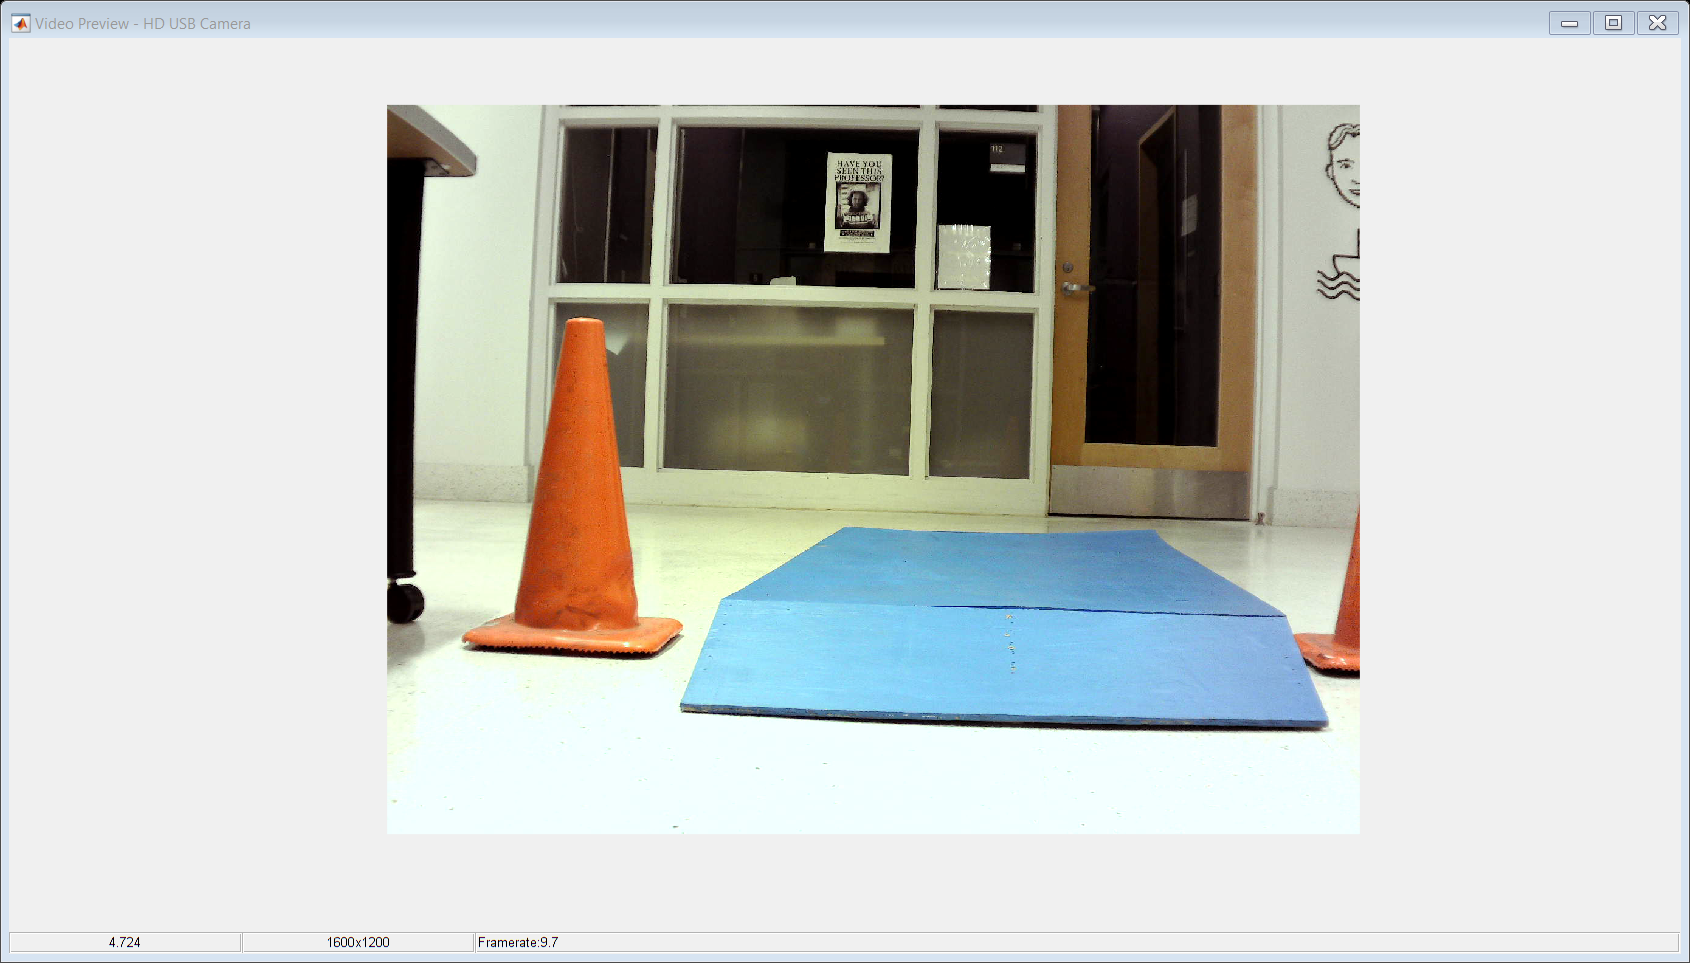

camera.show()

closepreview(camera.cam)

% Acquire a frame 
img = snapshot(camera.cam);

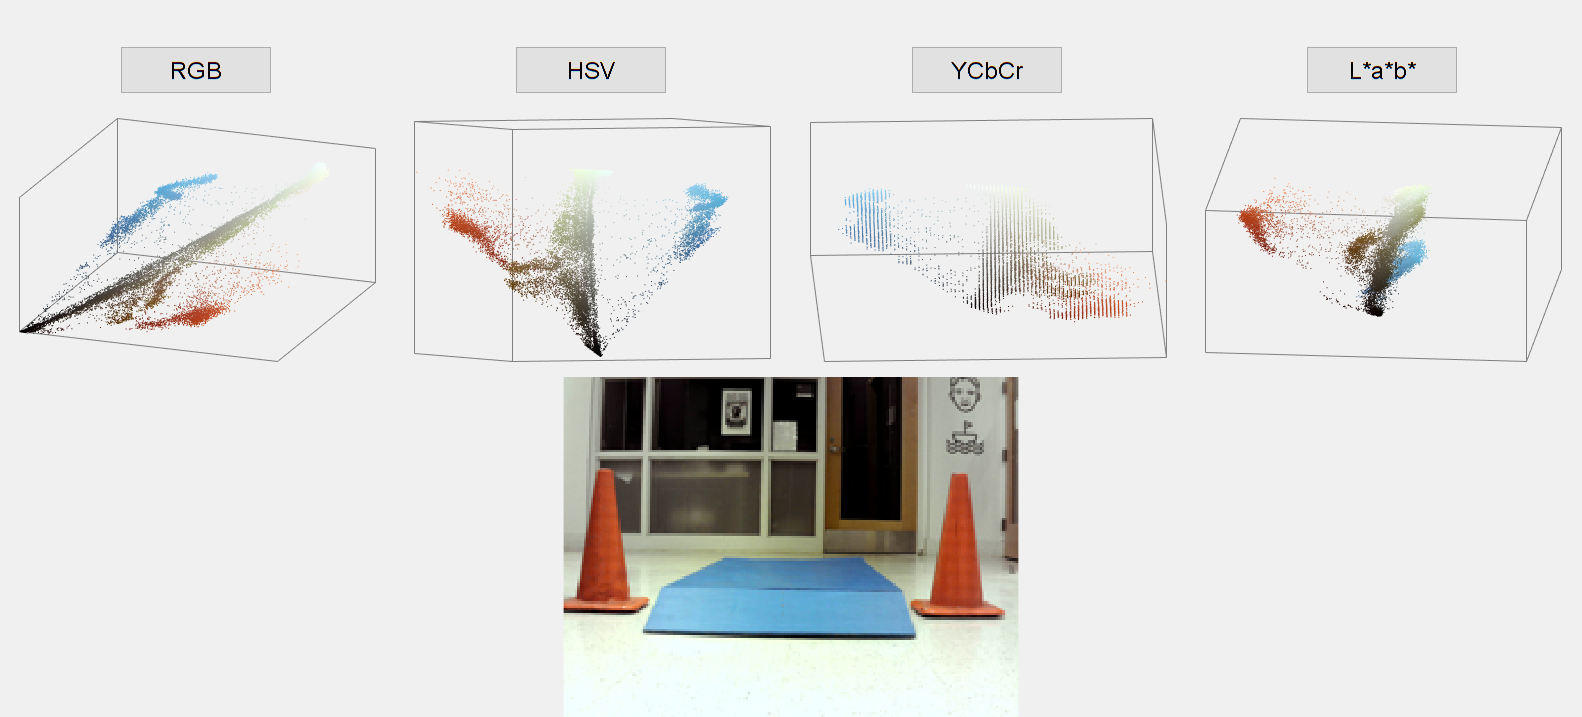

colorThresholder(img)

fig1 = figure

fig1 =   Figure (9) with properties:

      Number: 9
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [488 342 560 420]
       Units: 'pixels'

  Show all properties


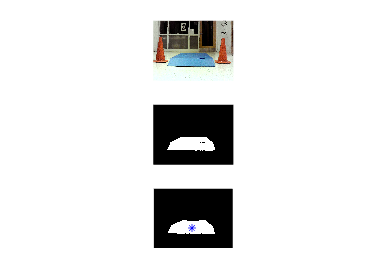

X-pixel value: 776.0424 
Y-pixel value: 788.4745 


targetX = 776.0424

[targetX, ~, ~] = getBridgeCord(img, true, fig1)


targetAngle = 180 - 180 * (targetX/1200)

targetAngle = 63.5936